# 3/21/2016 - DJC. This is an exploratory Beta-triggered stimulation script in preparation for the site visit and manuscript preparation 

Code to calculate distances between electrodes in grid

Starting with 0b5a2e 

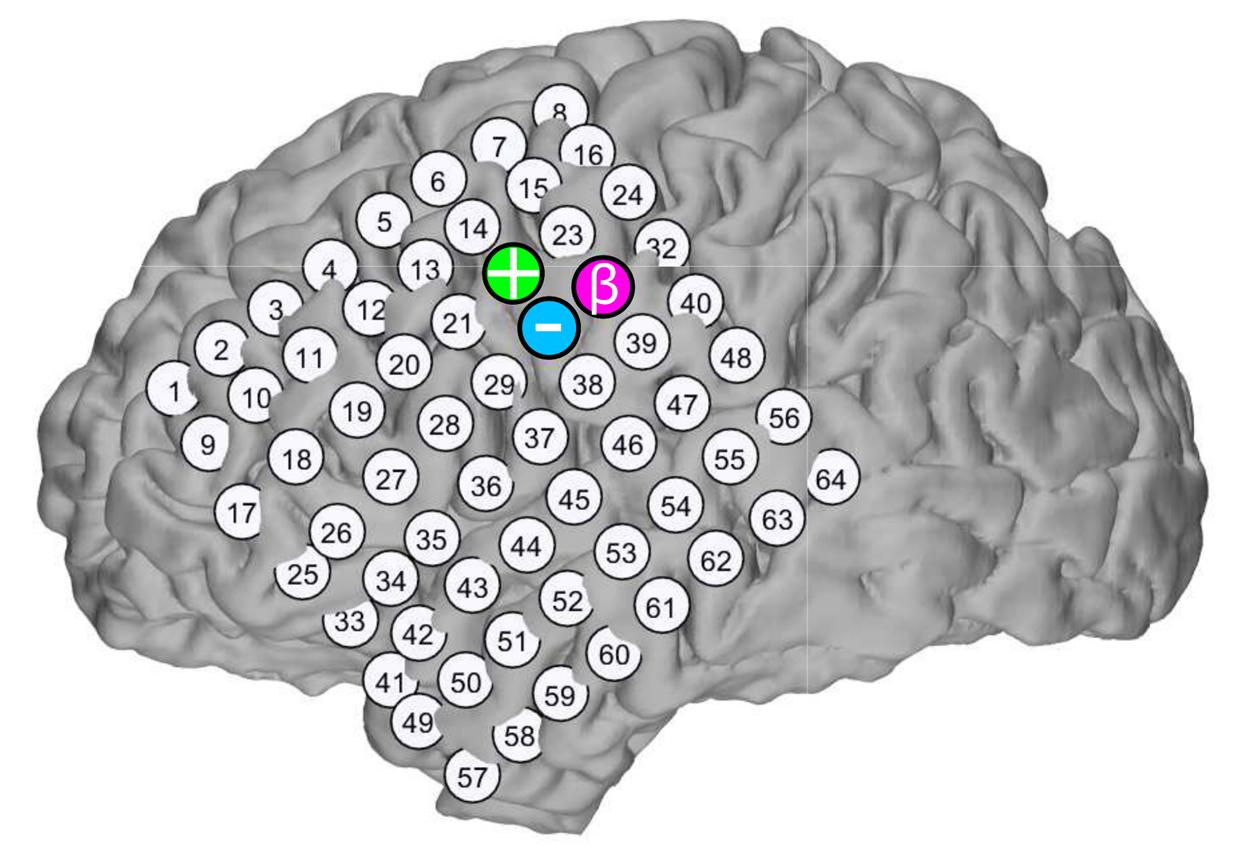

% sid
sid = '0b5a2e'

sid = 0b5a2e


% load montage
Montage.Montage = 64;
Montage.MontageTokenized = {'Grid(1:64)'};
Montage.MontageString = Montage.MontageTokenized{:};
Montage.MontageTrodes = zeros(64, 3);
Montage.BadChannels = [];
Montage.Default = true;

% get electrode locations
locs = trodeLocsFromMontage(sid, Montage, false);
Grid = locs;

% scatter plot of electrode locations
figure
c = linspace(1,10,size(locs,1));

% take labeling from plot dots direct
h = scatter3(locs(:,1),locs(:,2),locs(:,3),[100],c,'filled')

h =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
           SizeData: 100
          LineWidth: 0.5000
              XData: [1x64 double]
              YData: [1x64 double]
              ZData: [1x64 double]
              CData: [1x64 double]

  Show all properties


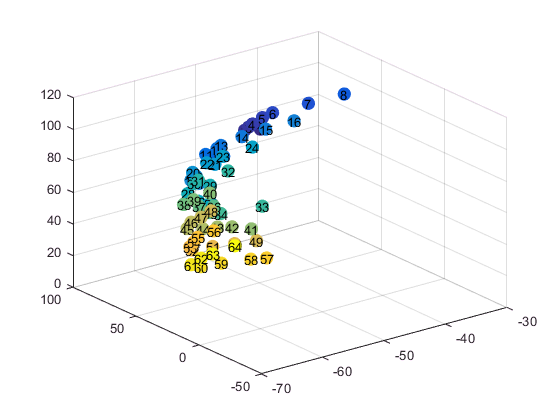



gridSize = 64;

trodeLabels = [1:gridSize];
for chan = 1:gridSize
    txt = num2str(trodeLabels(chan));
    t = text(locs(chan,1),locs(chan,2),locs(chan,3),txt,'FontSize',10,'HorizontalAlignment','center','VerticalAlignment','middle');
    set(t,'clipping','on');
end


% plot cortex too
figure
PlotCortex(sid,'l')
hold on
h = scatter3(locs(:,1),locs(:,2),locs(:,3),100,c,'filled')

h =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
           SizeData: 100
          LineWidth: 0.5000
              XData: [1x64 double]
              YData: [1x64 double]
              ZData: [1x64 double]
              CData: [1x64 double]

  Show all properties


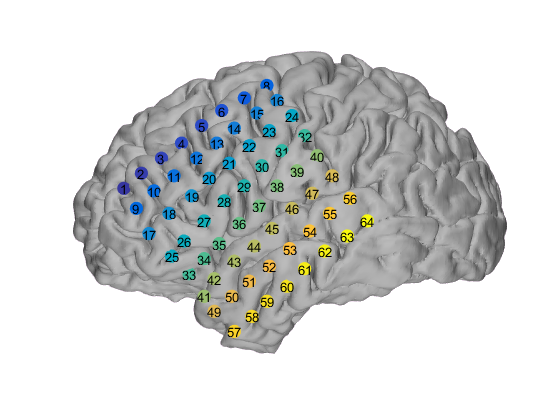

for chan = 1:gridSize
    txt = num2str(trodeLabels(chan));
    t = text(locs(chan,1),locs(chan,2),locs(chan,3),txt,'FontSize',10,'HorizontalAlignment','center','VerticalAlignment','middle');
    set(t,'clipping','on');
end

Now it's time to calculate the distances between objects

distances = matrixDist(locs);


calculate the distances from the stimulation sites, from the beta-triggered site?

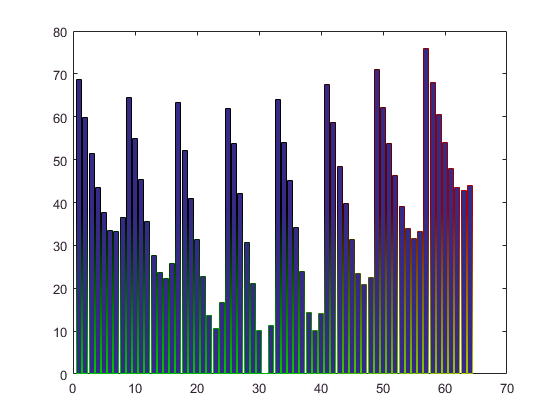

beta = 31;
stim1 = 22;
stim2 = 30;

betaDist = channelExtract(distances,beta);
stim1Dist = channelExtract(distances,stim1);
stim2Dist = channelExtract(distances,stim2);

figure
bar(betaDist)

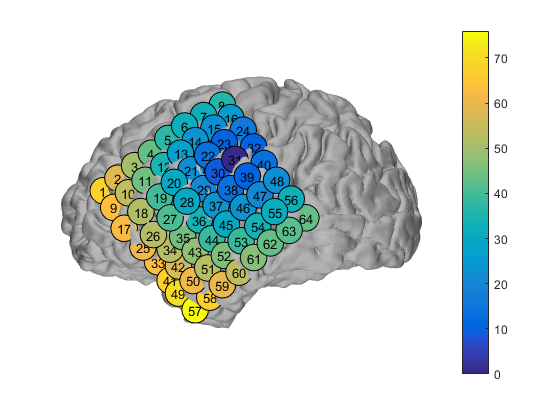


% plot distances

weights = betaDist;
clims = [min(betaDist) max(betaDist)];
figure
PlotDotsDirect(sid,locs,weights,determineHemisphereOfCoverage(sid), clims, 20,'parula', 1:gridSize, true);
% very often, after plotting the brain and dots, I add a colorbar for
% reference as to what the dot colors mean
colorbar;

Load in the important data 

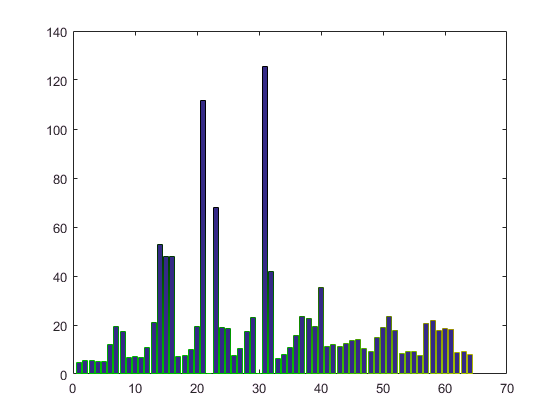

SUB_DIR = fullfile(myGetenv('subject_dir'));
OUTPUT_DIR = fullfile(myGetenv('OUTPUT_DIR'));
load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2eepSTATSsig'))
load tTemp.mat



chans = [1:64];
stims = [22 30];
logChans = chans;
logChans(stims) = 0;
logChans = logical(logChans);

for chan = chans
    if (chan~=stims)
        type1 = cell2mat([CCEPbyNumStim{chan}{1}{1:3}]);
        type2 = cell2mat([CCEPbyNumStim{chan}{2}{1:3}]);
        BigAveResp(chan) = (type1(14)+type2(14))/2;
        latencyResp(chan) = (type1(15)+type2(15))/2;
    end
end

figure
bar(BigAveResp)

Do a scatter plot of response vs. distance - > 5 stims

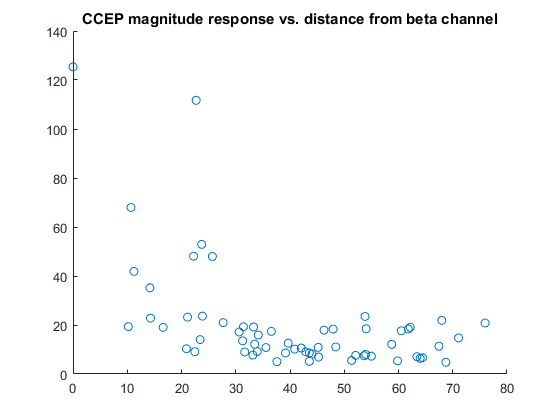

figure
scatter(betaDist(logChans),BigAveResp(logChans))
title('CCEP magnitude response vs. distance from beta channel')

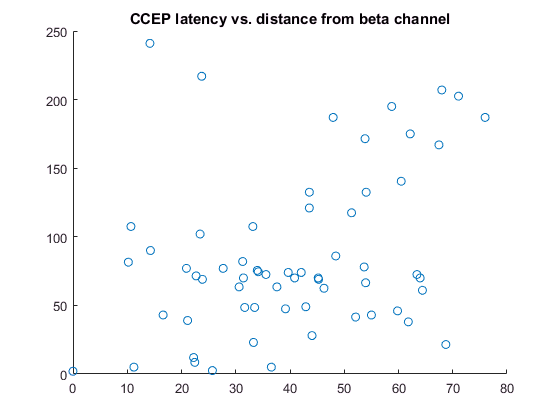


figure
scatter(betaDist(logChans),latencyResp(logChans))
title('CCEP latency vs. distance from beta channel')

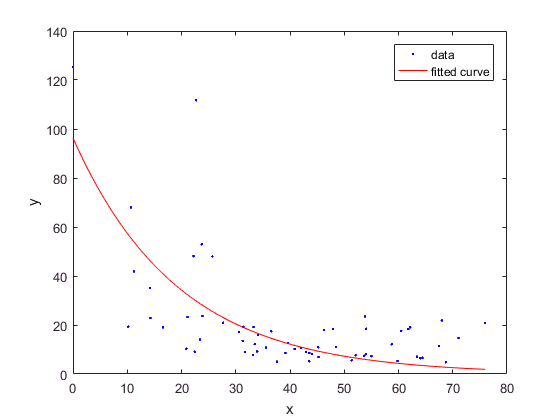


figure
[f,gof] = fit(betaDist(logChans)',BigAveResp(logChans)','exp1');
plot(f,betaDist(logChans),BigAveResp(logChans))

gof

gof =            sse: 1.5884e+04
       rsquare: 0.4636
           dfe: 60
    adjrsquare: 0.4546
          rmse: 16.2706


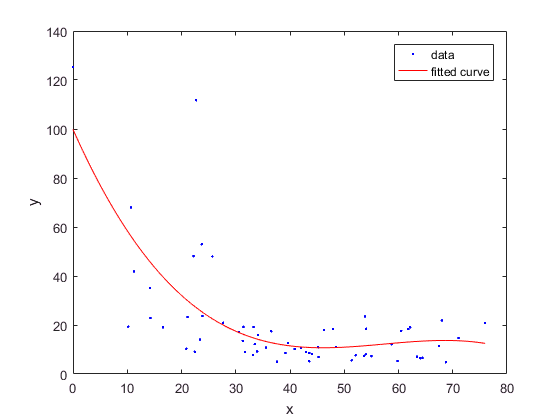


figure
[f,gof] = fit(betaDist(logChans)',BigAveResp(logChans)','poly3');
plot(f,betaDist(logChans),BigAveResp(logChans))

gof

gof =            sse: 1.4589e+04
       rsquare: 0.5073
           dfe: 58
    adjrsquare: 0.4818
          rmse: 15.8600


Do a scatter plot of response vs. distance -  3,4 stims

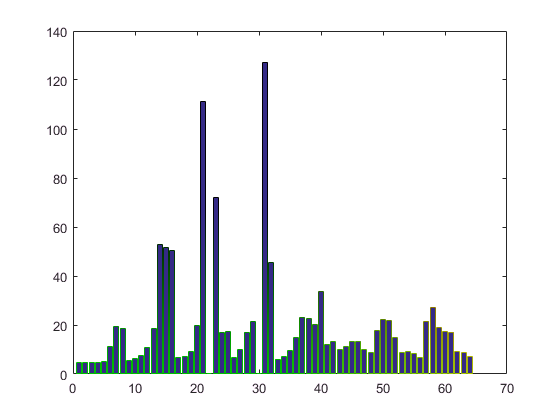

for chan = chans
    if (chan~=stims)
        type1 = cell2mat([CCEPbyNumStim{chan}{1}{1:3}]);
        type2 = cell2mat([CCEPbyNumStim{chan}{2}{1:3}]);
        BigAveResp(chan) = (type1(8)+type2(8))/2;
        latencyResp(chan) = (type1(9)+type2(9))/2;
        
    end
end


figure
bar(BigAveResp)

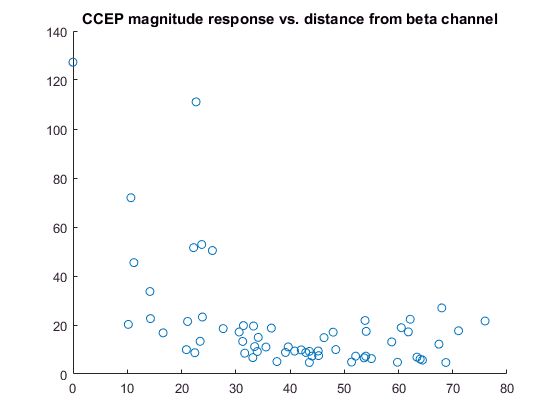


figure
scatter(betaDist(logChans),BigAveResp(logChans))
title('CCEP magnitude response vs. distance from beta channel')

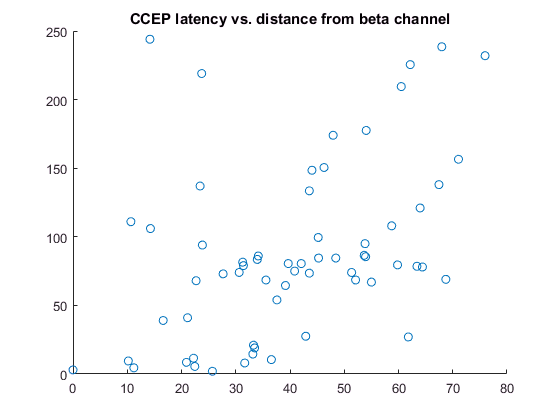


figure
scatter(betaDist(logChans),latencyResp(logChans))
title('CCEP latency vs. distance from beta channel')


figure
[f,gof] = fit(betaDist(logChans)',BigAveResp(logChans)','exp1','Robust','LAR')

f =      General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       60.51  (54.73, 66.28)
       b =    -0.04131  (-0.04543, -0.03719)

gof =            sse: 1.0144e+03
       rsquare: 0.9674
           dfe: 60
    adjrsquare: 0.9669
          rmse: 4.1117


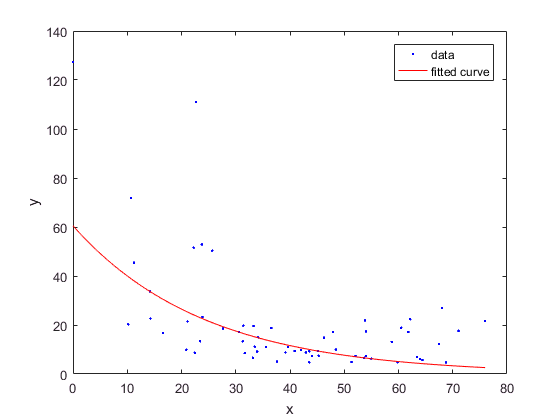

plot(f,betaDist(logChans),BigAveResp(logChans))

gof

gof =            sse: 1.0144e+03
       rsquare: 0.9674
           dfe: 60
    adjrsquare: 0.9669
          rmse: 4.1117


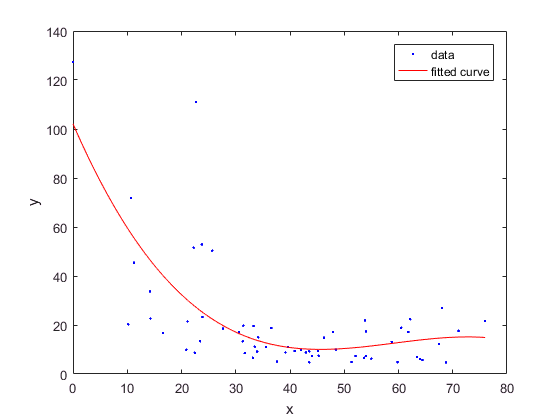


figure
[f,gof] = fit(betaDist(logChans)',BigAveResp(logChans)','poly3');
plot(f,betaDist(logChans),BigAveResp(logChans))

gof

gof =            sse: 1.5218e+04
       rsquare: 0.5113
           dfe: 58
    adjrsquare: 0.4860
          rmse: 16.1982


Do a scatter plot of response vs. distance - 1,2 stims 

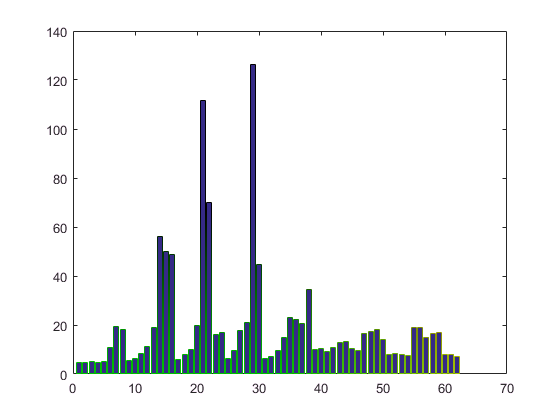


for chan = chans
    if (chan~=stims)
        type1 = cell2mat([CCEPbyNumStim{chan}{1}{1:3}]);
        type2 = cell2mat([CCEPbyNumStim{chan}{2}{1:3}]);
        BigAveResp(chan) = (type1(2)+type2(2))/2;
        latencyResp(chan) = (type1(3)+type2(3))/2;
        
    end
end

figure
bar(BigAveResp(logChans))

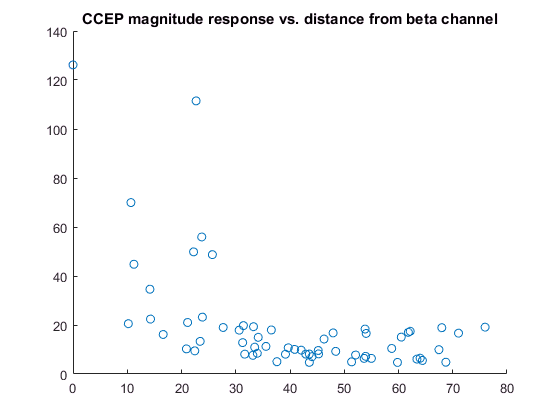


figure
scatter(betaDist(logChans),BigAveResp(logChans))
title('CCEP magnitude response vs. distance from beta channel')

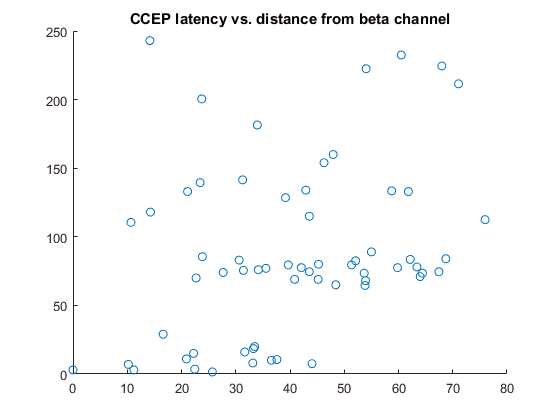


figure
scatter(betaDist(logChans),latencyResp(logChans))
title('CCEP latency vs. distance from beta channel')

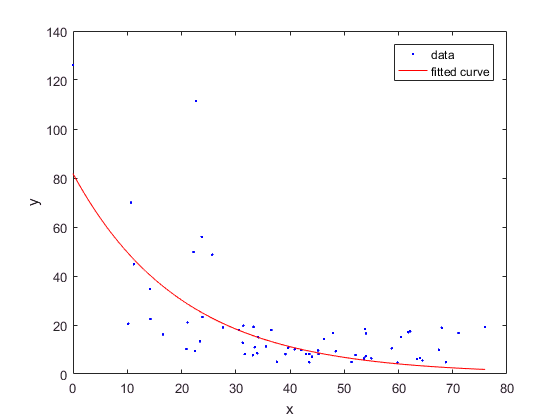


figure
[f,gof] = fit(betaDist',BigAveResp','exp1');
plot(f,betaDist(logChans),BigAveResp(logChans))

gof

gof =            sse: 2.0562e+04
       rsquare: 0.3490
           dfe: 62
    adjrsquare: 0.3385
          rmse: 18.2113


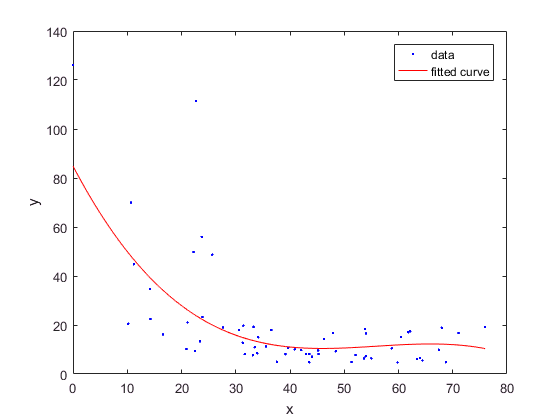


figure
[f,gof] = fit(betaDist',BigAveResp','poly3');
plot(f,betaDist(logChans),BigAveResp(logChans))

gof

gof =            sse: 1.9651e+04
       rsquare: 0.3778
           dfe: 60
    adjrsquare: 0.3467
          rmse: 18.0973


# Ok - time to look at everyone

sid = d5cd55

gof =            sse: 2.3001e+04
       rsquare: 5.4092e-06
           dfe: 60
    adjrsquare: -0.0167
          rmse: 19.5792


gof =            sse: 1.0985e+04
       rsquare: 0.5224
           dfe: 58
    adjrsquare: 0.4977
          rmse: 13.7624


sid = c91479

gof =            sse: 5.5748e+03
       rsquare: 0.2766
           dfe: 60
    adjrsquare: 0.2646
          rmse: 9.6391


gof =            sse: 4.2358e+03
       rsquare: 0.4504
           dfe: 58
    adjrsquare: 0.4219
          rmse: 8.5458


sid = 7dbdec

gof =            sse: 2.4791e+05
       rsquare: 2.6256e-06
           dfe: 60
    adjrsquare: -0.0167
          rmse: 64.2790


gof =            sse: 2.3938e+05
       rsquare: 0.0344
           dfe: 58
    adjrsquare: -0.0155
          rmse: 64.2433


sid = 9ab7ab

gof =            sse: 728.1505
       rsquare: 0.3098
           dfe: 60
    adjrsquare: 0.2983
          rmse: 3.4837


gof =            sse: 639.3584
       rsquare: 0.3940
           dfe: 58
    adjrsquare: 0.3626
          rmse: 3.3202


sid = 702d24

gof =            sse: 8.4722e+03
       rsquare: 0.0770
           dfe: 60
    adjrsquare: 0.0616
          rmse: 11.8829


gof =            sse: 8.0947e+03
       rsquare: 0.1181
           dfe: 58
    adjrsquare: 0.0725
          rmse: 11.8137


sid = ecb43e

gof =            sse: 8.3674e+03
       rsquare: 0.0884
           dfe: 60
    adjrsquare: 0.0732
          rmse: 11.8092


gof =            sse: 7.9181e+03
       rsquare: 0.1373
           dfe: 58
    adjrsquare: 0.0927
          rmse: 11.6841


sid = 0b5a2e

gof =            sse: 1.5884e+04
       rsquare: 0.4636
           dfe: 60
    adjrsquare: 0.4546
          rmse: 16.2706


gof =            sse: 1.4589e+04
       rsquare: 0.5073
           dfe: 58
    adjrsquare: 0.4818
          rmse: 15.8600


sid = 0b5a2ePlayback

gof =            sse: 1.3738e+04
       rsquare: 0.4977
           dfe: 60
    adjrsquare: 0.4894
          rmse: 15.1318


gof =            sse: 1.2605e+04
       rsquare: 0.5392
           dfe: 58
    adjrsquare: 0.5153
          rmse: 14.7420


sid = 0a80cf

Index exceeds matrix dimensions.


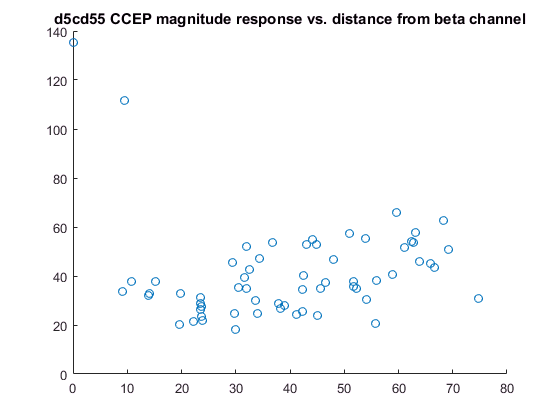

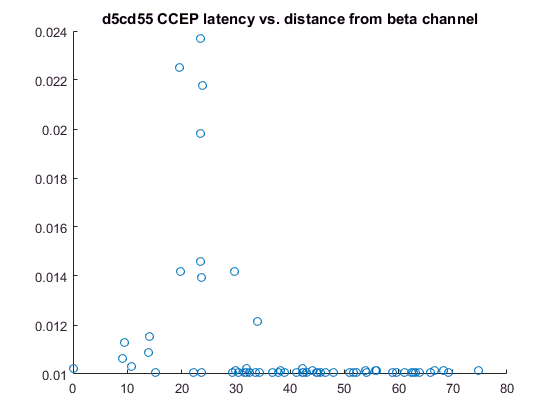

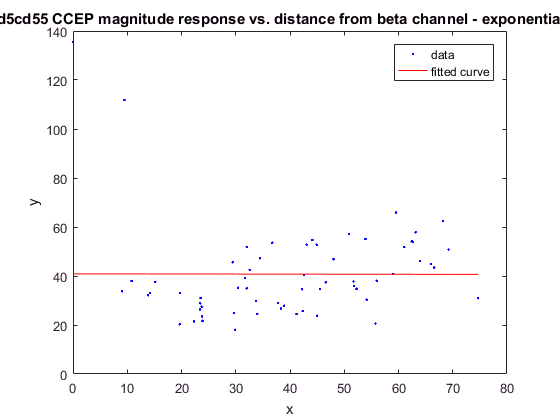

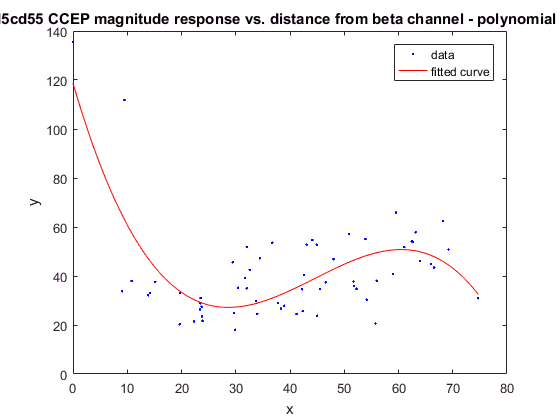

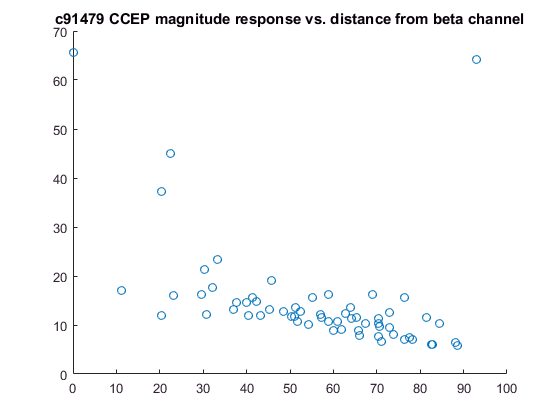

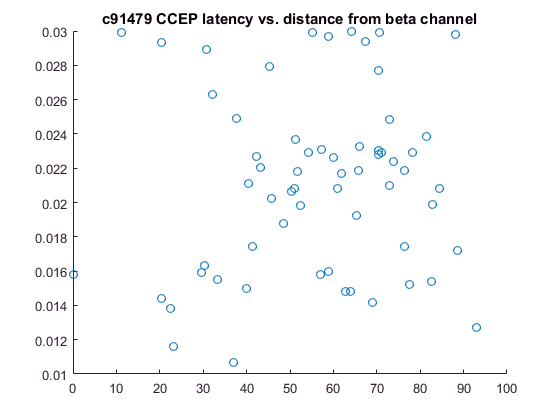

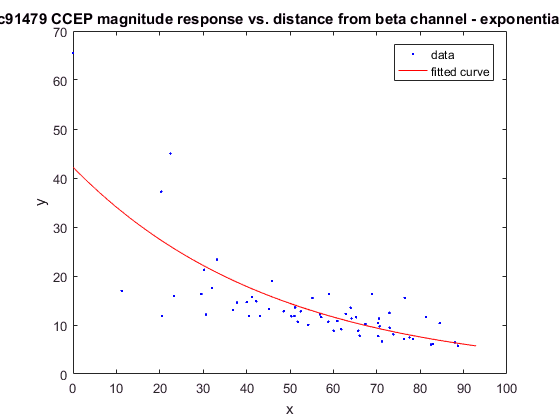

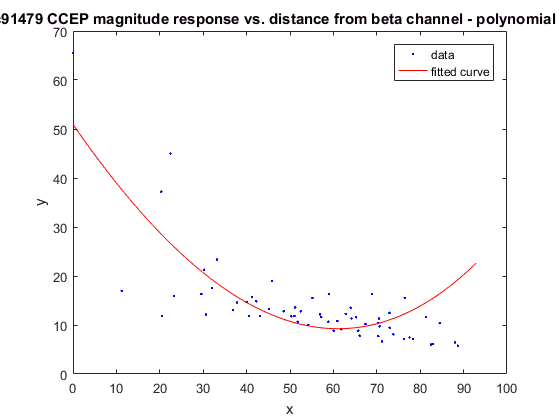

close all;clear all;clc
Z_Constants;
SUB_DIR = fullfile(myGetenv('subject_dir'));
OUTPUT_DIR = fullfile(myGetenv('OUTPUT_DIR'));

for i = 2:length(SIDS)-1
    sid = SIDS{i}
    switch sid
        case 'd5cd55'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','d5cd55epSTATSsig'))
            stims = [54 62];
            
            betaChan = 53;
        case 'c91479'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','c91479epSTATSsig'))
            betaChan = 64;
            stims = [55 56];
            
        case '7dbdec'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','7dbdecepSTATSsig'))
            stims = [11 12];
            
            betaChan = 4;
        case '9ab7ab'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','9ab7abepSTATSsig'))
            betaChan = 51;
            stims = [59 60];
            
        case '702d24'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','702d24epSTATSsig'))
            betaChan = 5;
            stims = [13 14];
            
            %         case 'ecb43e'
            %             load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','ecb43eepSTATSsig'))
            %             betaChan = 55;
            %             stims = [56 64];
            
        case '0b5a2e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2eepSTATSsig'))
            betaChan = 31;
            stims = [22 30];
            
        case '0b5a2ePlayback'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2ePlaybackepSTATSsig'))
            betaChan = 31;
            stims = [22 30];
            
    end
    
    
    load tTemp.mat
    subjid = sid;
    if (strcmp(sid,'0b5a2ePlayback'))
        load(fullfile(getSubjDir('0b5a2e'), 'trodes.mat'));
    else
        load(fullfile(getSubjDir(subjid),'trodes.mat'))
    end
    
    
    locs = Grid;
%     
%     % scatter plot of electrode locations
%     figure
%     c = linspace(1,10,size(locs,1));
%     
%     % take labeling from plot dots direct
%     h = scatter3(locs(:,1),locs(:,2),locs(:,3),[100],c,'filled');
%     
%     
%     gridSize = 64;
%     
%     trodeLabels = [1:gridSize];
%     for chan = 1:gridSize
%         txt = num2str(trodeLabels(chan));
%         t = text(locs(chan,1),locs(chan,2),locs(chan,3),txt,'FontSize',10,'HorizontalAlignment','center','VerticalAlignment','middle');
%         set(t,'clipping','on');
%     end
%     
%     % plot cortex too
%     figure
%     sidToPlot = subjid;
%     if strcmp(subjid,'0b5a2ePlayback')
%         sidToPlot = '0b5a2e';
%     end
%     PlotCortex(sidToPlot,'l')
%     hold on
%     h = scatter3(locs(:,1),locs(:,2),locs(:,3),100,c,'filled')
%     for chan = 1:gridSize
%         txt = num2str(trodeLabels(chan));
%         t = text(locs(chan,1),locs(chan,2),locs(chan,3),txt,'FontSize',10,'HorizontalAlignment','center','VerticalAlignment','middle');
%         set(t,'clipping','on');
%     end

% DJC 5-30-2016 additions to look at timing 

distances = matrixDist(locs);


betaDist = channelExtract(distances,betaChan);
stim1Dist = channelExtract(distances,stims(1));
stim2Dist = channelExtract(distances,stims(2));

chans = [1:64];
logChans = chans;
logChans(stims) = 0;
logChans = logical(logChans);

% for greater than 5 stims 
for chan = chans
    if (chan~=stims)
        if strcmp(sid,'0b5a2e') || strcmp(sid,'0b5a2ePlayback')
            
        type1 = cell2mat([CCEPbyNumStim{chan}{1}{1:3}]);
        type2 = cell2mat([CCEPbyNumStim{chan}{2}{1:3}]);
        BigAveResp(chan) = (type1(14)+type2(14))/2;
        latencyResp(chan) = (type1(15)+type2(15))/2;
        else
            % temporary work around DJC 5-30-2016 
                    type1 = cell2mat([CCEPbyNumStim{chan}{1}{1:3}]);
        BigAveResp(chan) = type1(14);
        latencyResp(chan) = type1(15);

        end
    end
end

% for greater than 5 stims 
figure
scatter(betaDist(logChans),BigAveResp(logChans))
title([sid,' CCEP magnitude response vs. distance from beta channel'])

figure
scatter(betaDist(logChans),latencyResp(logChans))
title([sid, ' CCEP latency vs. distance from beta channel'])

figure
[f,gof] = fit(betaDist(logChans)',BigAveResp(logChans)','exp1');
plot(f,betaDist(logChans),BigAveResp(logChans))
title([sid,' CCEP magnitude response vs. distance from beta channel - exponential fit'])

gof

figure
[f,gof] = fit(betaDist(logChans)',BigAveResp(logChans)','poly3');
plot(f,betaDist(logChans),BigAveResp(logChans))
title([sid,' CCEP magnitude response vs. distance from beta channel - polynomial 3 fit'])

gof


end

calculate the distances from the stimulation sites, from the beta-triggered site?

distances = matrixDist(locs);


betaDist = channelExtract(distances,betaChan);
stim1Dist = channelExtract(distances,stims(1));
stim2Dist = channelExtract(distances,stims(2));

figure
bar(betaDist)


% plot distances

weights = betaDist;
clims = [min(betaDist) max(betaDist)];
figure
PlotDotsDirect(sidToPlot,locs,weights,determineHemisphereOfCoverage(sidToPlot), clims, 20,'parula', 1:gridSize, true);
% very often, after plotting the brain and dots, I add a colorbar for
% reference as to what the dot colors mean
colorbar;

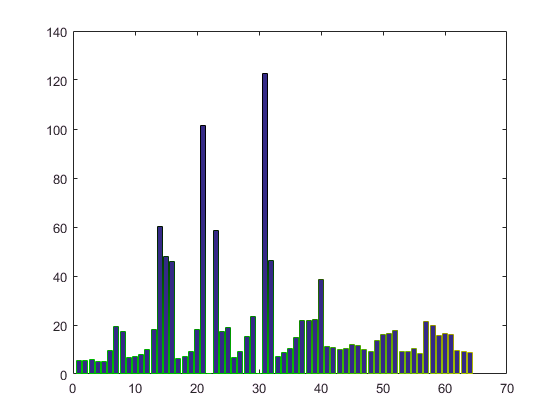

chans = [1:64];
logChans = chans;
logChans(stims) = 0;
logChans = logical(logChans);

for chan = chans
    if (chan~=stims)
        type1 = cell2mat([CCEPbyNumStim{chan}{1}{1:3}]);
        type2 = cell2mat([CCEPbyNumStim{chan}{2}{1:3}]);
        BigAveResp(chan) = (type1(14)+type2(14))/2;
        latencyResp(chan) = (type1(15)+type2(15))/2;
    end
end

figure
bar(BigAveResp)

Do a scatter plot of response vs. distance - > 5 stims

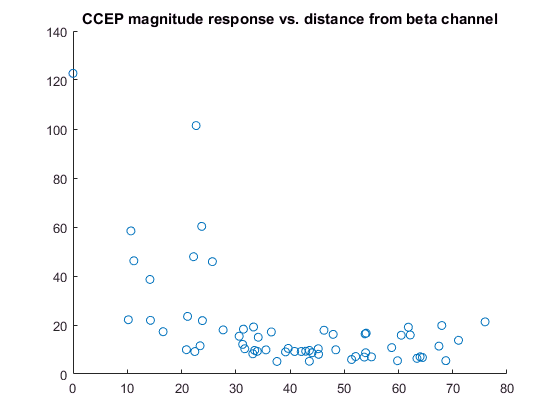

figure
scatter(betaDist(logChans),BigAveResp(logChans))
title('CCEP magnitude response vs. distance from beta channel')

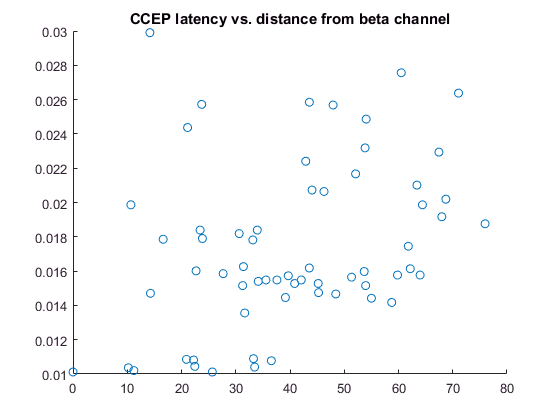


figure
scatter(betaDist(logChans),latencyResp(logChans))
title('CCEP latency vs. distance from beta channel')

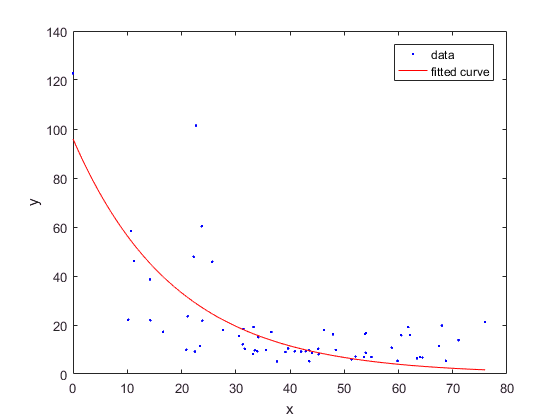


figure
[f,gof] = fit(betaDist(logChans)',BigAveResp(logChans)','exp1');
plot(f,betaDist(logChans),BigAveResp(logChans))

gof

gof =            sse: 1.3738e+04
       rsquare: 0.4977
           dfe: 60
    adjrsquare: 0.4894
          rmse: 15.1318


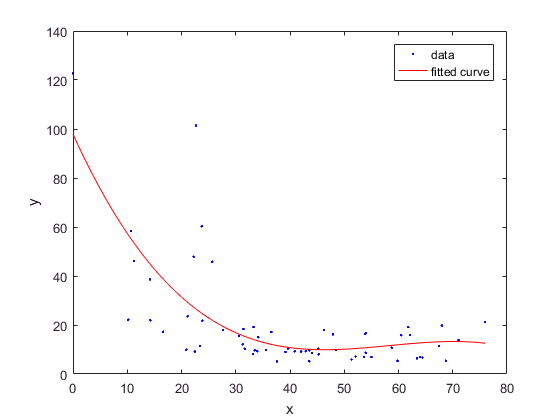


figure
[f,gof] = fit(betaDist(logChans)',BigAveResp(logChans)','poly3');
plot(f,betaDist(logChans),BigAveResp(logChans))

gof

gof =            sse: 1.2605e+04
       rsquare: 0.5392
           dfe: 58
    adjrsquare: 0.5153
          rmse: 14.7420


Do a scatter plot of response vs. distance -  3,4 stims

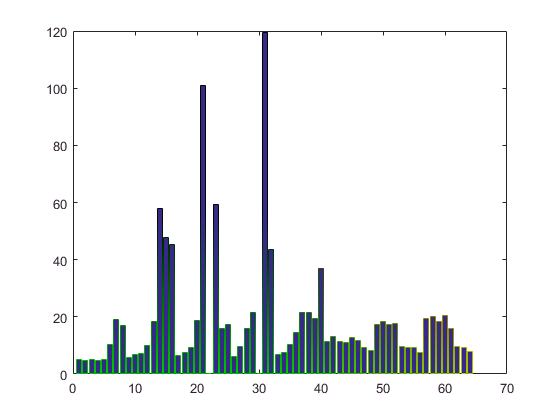

for chan = chans
    if (chan~=stims)
        type1 = cell2mat([CCEPbyNumStim{chan}{1}{1:3}]);
        type2 = cell2mat([CCEPbyNumStim{chan}{2}{1:3}]);
        BigAveResp(chan) = (type1(8)+type2(8))/2;
        latencyResp(chan) = (type1(9)+type2(9))/2;
        
    end
end


figure
bar(BigAveResp)

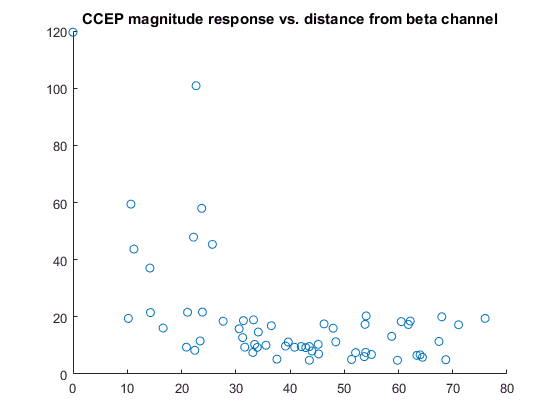


figure
scatter(betaDist(logChans),BigAveResp(logChans))
title('CCEP magnitude response vs. distance from beta channel')

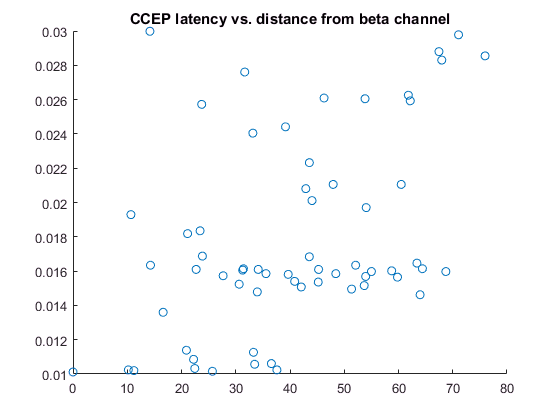


figure
scatter(betaDist(logChans),latencyResp(logChans))
title('CCEP latency vs. distance from beta channel')


figure
[f,gof] = fit(betaDist(logChans)',BigAveResp(logChans)','exp1','Robust','LAR')

f =      General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       72.12  (66.5, 77.74)
       b =    -0.04696  (-0.05065, -0.04328)

gof =            sse: 848.3502
       rsquare: 0.9678
           dfe: 60
    adjrsquare: 0.9673
          rmse: 3.7602


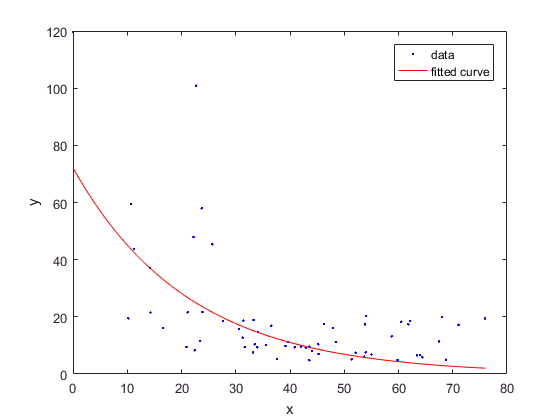

plot(f,betaDist(logChans),BigAveResp(logChans))

gof

gof =            sse: 848.3502
       rsquare: 0.9678
           dfe: 60
    adjrsquare: 0.9673
          rmse: 3.7602


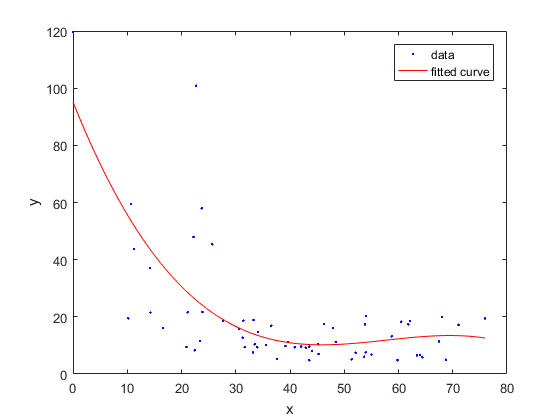


figure
[f,gof] = fit(betaDist(logChans)',BigAveResp(logChans)','poly3');
plot(f,betaDist(logChans),BigAveResp(logChans))

gof

gof =            sse: 1.2730e+04
       rsquare: 0.5167
           dfe: 58
    adjrsquare: 0.4917
          rmse: 14.8150


Do a scatter plot of response vs. distance - 1,2 stims 

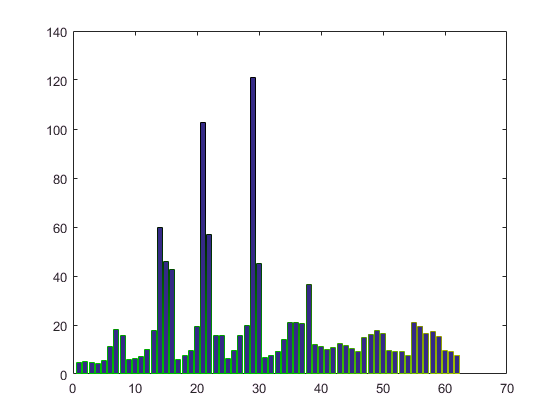


for chan = chans
    if (chan~=stims)
        type1 = cell2mat([CCEPbyNumStim{chan}{1}{1:3}]);
        type2 = cell2mat([CCEPbyNumStim{chan}{2}{1:3}]);
        BigAveResp(chan) = (type1(2)+type2(2))/2;
        latencyResp(chan) = (type1(3)+type2(3))/2;
        
    end
end

figure
bar(BigAveResp(logChans))

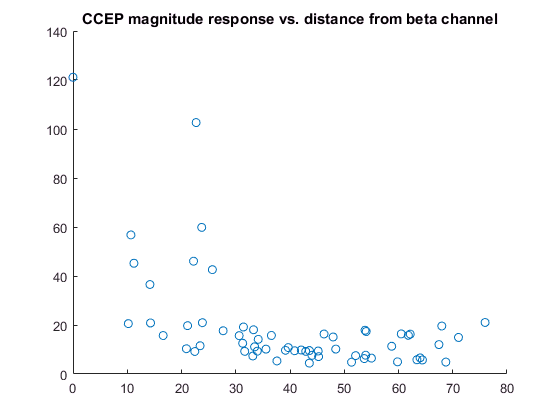


figure
scatter(betaDist(logChans),BigAveResp(logChans))
title('CCEP magnitude response vs. distance from beta channel')

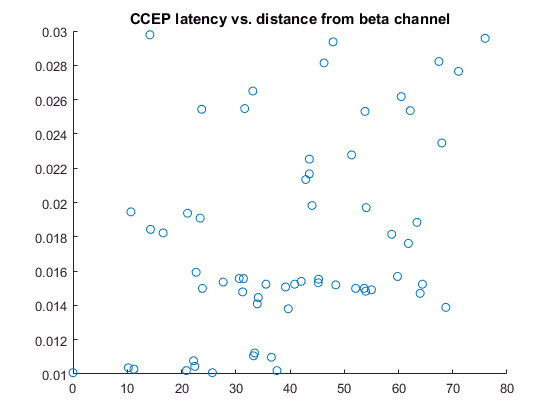


figure
scatter(betaDist(logChans),latencyResp(logChans))
title('CCEP latency vs. distance from beta channel')

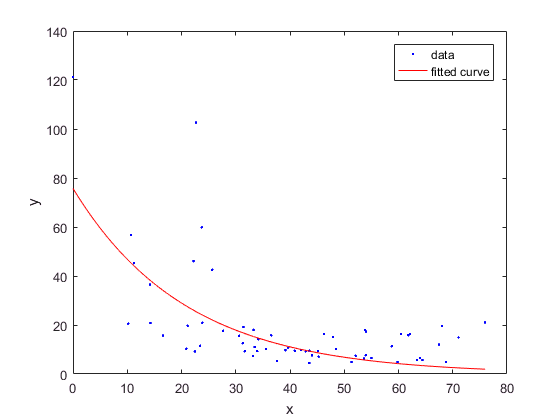


figure
[f,gof] = fit(betaDist',BigAveResp','exp1');
plot(f,betaDist(logChans),BigAveResp(logChans))

gof

gof =            sse: 1.8207e+04
       rsquare: 0.3375
           dfe: 62
    adjrsquare: 0.3268
          rmse: 17.1365


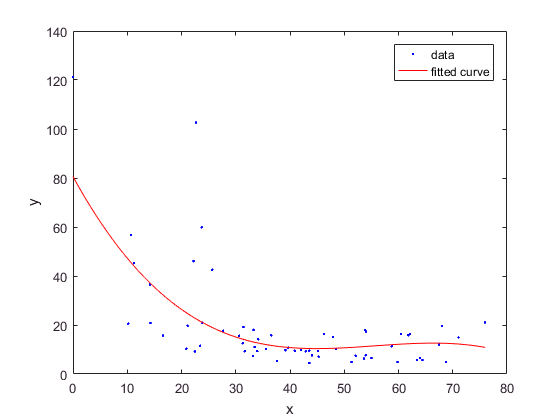


figure
[f,gof] = fit(betaDist',BigAveResp','poly3');
plot(f,betaDist(logChans),BigAveResp(logChans))

gof

gof =            sse: 1.7127e+04
       rsquare: 0.3768
           dfe: 60
    adjrsquare: 0.3456
          rmse: 16.8954
